% Carica un'immagine di esempio in scala di grigi
I = imread('peppers.png');
I = im2double(I);

% Parametri del rumore a bande
amplitude = 0.15;
frequency = 25;
[rows, cols, ~] = size(I);
[yGrid, ~] = meshgrid(1:cols, 1:rows);
stripe_pattern = amplitude * sin(2 * pi * frequency * yGrid / rows);

I_noisy = zeros(size(I));
for c = 1:3
    I_noisy(:,:,c) = mat2gray(I(:,:,c) + stripe_pattern);
end

Algoritmo di Denoising Verticale

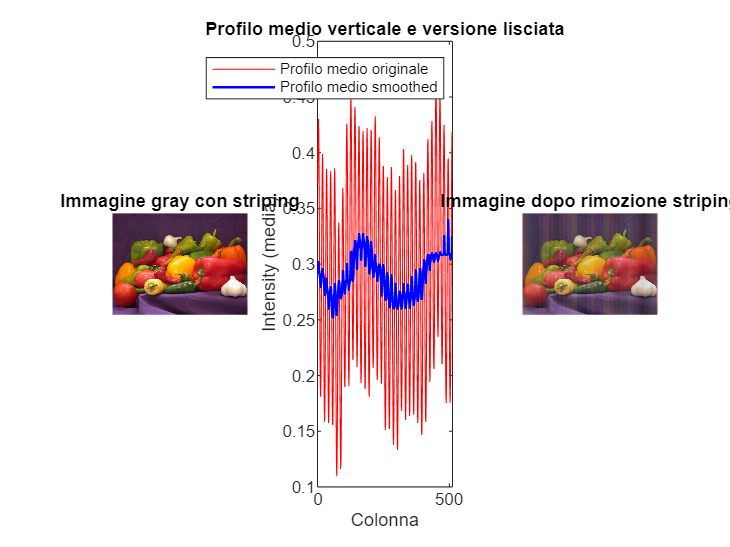

I_rgb = im2double(I_noisy);
imwrite(I_noisy,'peppers_vertical_stripes.jpg')

[M, N, C] = size(I_rgb);
I_denoised = zeros(size(I_rgb));
windowSize = 100;
for c = 1:C
    channel = I_rgb(:,:,c);
    p = mean(channel, 1);
    p_smooth = medfilt1(p, windowSize, 'truncate');
    stripe_profile = p - p_smooth;
    stripe_matrix = repmat(stripe_profile, M, 1);
    denoised_channel = channel - stripe_matrix;
    denoised_channel = min(max(denoised_channel, 0), 1);
    I_denoised(:,:,c) = denoised_channel;
end

% 8) Mostra i risultati
figure;
subplot(1,3,1);
imshow(I);
title('Immagine gray con striping');

subplot(1,3,2);
plot(p, 'r'); hold on;
plot(p_smooth, 'b', 'LineWidth', 1.2);
legend('Profilo medio originale','Profilo medio smoothed');
title('Profilo medio verticale e versione lisciata');
xlabel('Colonna');
ylabel('Intensity (media)');

subplot(1,3,3);
imshow(I_denoised);
title('Immagine dopo rimozione striping');

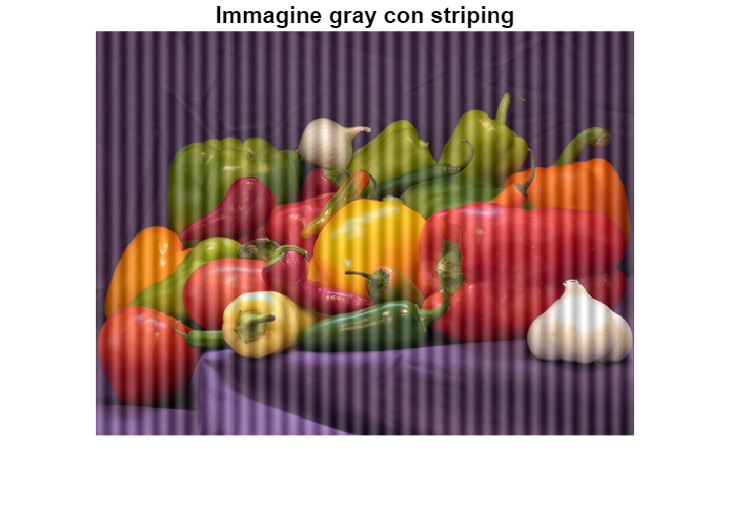


figure
imshow(I_rgb);
title('Immagine gray con striping');

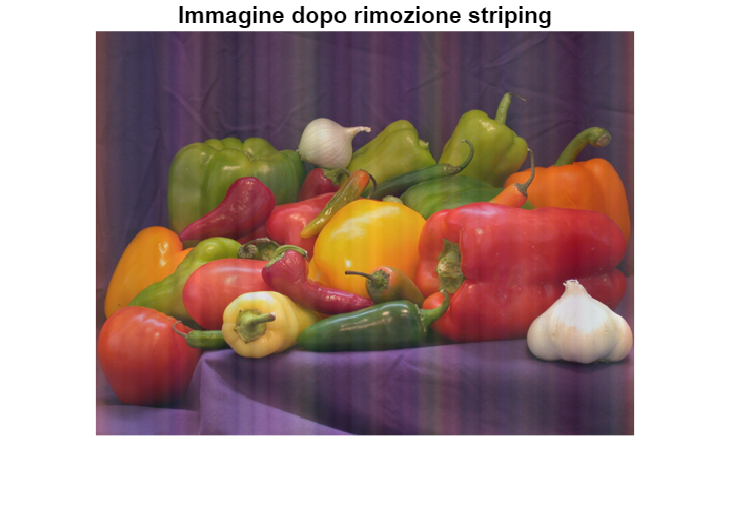

figure
imshow(I_denoised);
title('Immagine dopo rimozione striping');

I = imread('peppers.png');
I = im2double(I);

% Parametri del rumore a bande
amplitude = 0.15;
frequency = 20;
[rows, cols, ~] = size(I);
[~, yGrid] = meshgrid(1:cols, 1:rows);
stripe_pattern = amplitude * sin(2 * pi * frequency * yGrid / rows);

I_noisy = zeros(size(I));
for c = 1:3
    I_noisy(:,:,c) = mat2gray(I(:,:,c) + stripe_pattern);
end

Algoritmo Denoising Orizzontale

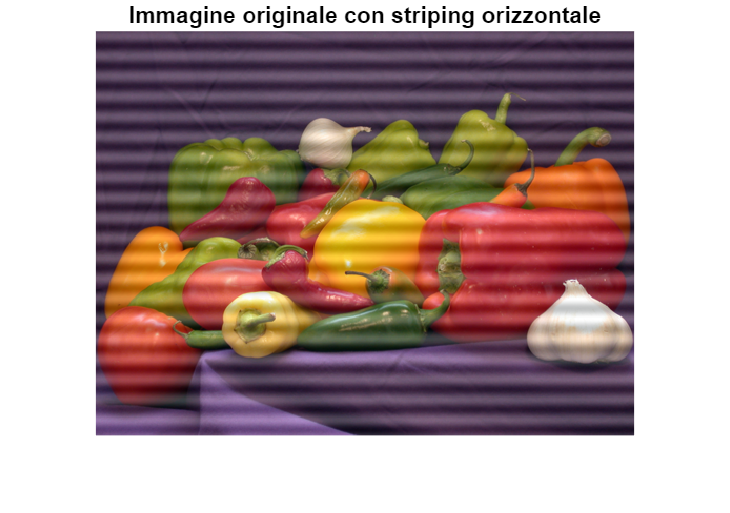

I_rgb = im2double(I_noisy);

imwrite(I_noisy,'peppers_horizontal_stripes.jpg')
[M, N, C] = size(I_rgb);
I_denoised = zeros(size(I_rgb));
windowSize = 75;
for c = 1:C
    channel = I_rgb(:,:,c);
    p = mean(channel, 2);
    p_smooth = medfilt1(p, windowSize, 'truncate');
    stripe_profile = p - p_smooth;
    stripe_matrix = repmat(stripe_profile, 1, N);
    channel_denoised = channel - stripe_matrix;
    channel_denoised = min(max(channel_denoised, 0), 1);
    I_denoised(:,:,c) = channel_denoised;
end
figure;
imshow(I_rgb); title('Immagine originale con striping orizzontale');

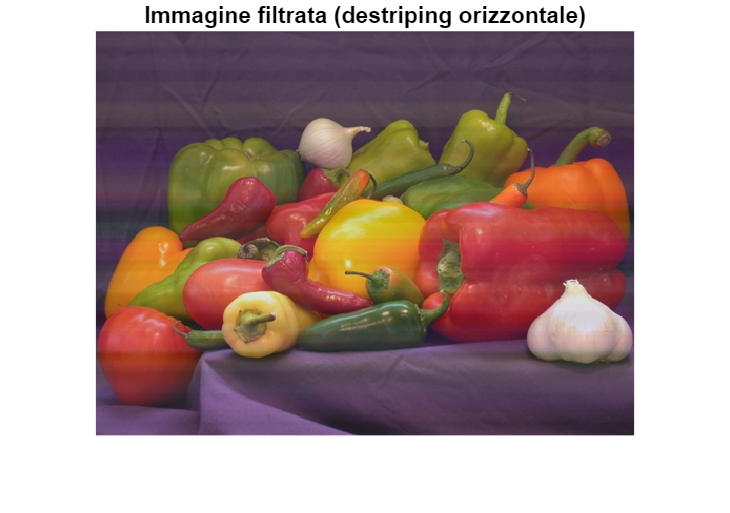

imshow(I_denoised); title('Immagine filtrata (destriping orizzontale)');